# Color Performance Review Tool for Endoscopy Devices - User's Manual

## 1. Introduction

The Color Performance Review (CPR) Tool for Endoscopy Devices is a software program written in Matlab for analyzing color performance testing data in endoscopy device. The tool accepts the testing data and then generates quantitative analyses for the user to compare color performance between devices. The input testing data include the measurement data of a standard test target from the device output as well as the ground truth of the test target. 

The tool provides the following analyses: 

- Visual simulation of the test target and sample scenes

- Absolute color errors in comparison with the ground truth

- Preservation of the patch order in lightness, hue, and chroma

- Preservation of color contrast between patches

### 1.1 Software Requirements

- Matlab Runtime 9.12 (Version 9.12 tested)

- Matlab (Version 9.12 tested)

- Image Processing Toolbox (Version 11.5 tested)

- Computer Vision Toolbox (Version 9.12 tested)

- Statistics and Machine Learning Toolbox (Version 12.3 tested)

## 2. Data Processing

### 2.0 Data Preparation

The input data should include the measured CIEXYZ values of the 24-patch [ColorChecker](https://www.xrite.com/categories/calibration-profiling/colorchecker-classic-family/colorchecker-classic-nano) for the test target and the endoscopy device. The input files are text files in the comma-separated value (CSV) format. Each input file contains 25 rows of the CIE X, Y, and Z values separated by commas. Lines #1~#24 describe the 24 color patches, and Line #25 describes the reference white. Follow the patch order defined by the ColorChecker.

The following is a sample input file:

type('XYZ_Subject.csv')

19.1,16.2,8.9
76.6,72.2,58.4
40.6,41.7,80.7
20.1,26.4,9.8
61.3,58.6,99.5
80.7,95,106.7
66.8,58.4,12.1
24.5,20.3,77.6
47.3,29.1,24.3
5.5,3.3,12.1
66.5,85.1,19.3
74.1,74.9,11.2
10.8,6.8,46
29.3,46.6,15.1
29.2,16.4,5.3
95,107.4,14.7
56.4,38,69.2
44.2,51.1,100.4
167.3,174.2,193.4
124.8,130.3,145.4
88.1,92.2,103.4
45.2,47.3,52.6
13.6,14.2,17.4
0.6,0.6,0.8
167.3,174.2,193.4


*Figure 2.0: CIEXYZ input file. A sample input file of the CIEXYZ data measured from the device.*

### 2.1 Import Data

Provide filenames for loading data files that contain the measured CIEXYZ values of the 24-patch ColorChecker for the test target (e.g., 'XYZ_Reference.csv') and the subject device (e.g., 'XYZ_Subject.csv'): 

XYZ_Reference_filename = "XYZ_Reference.csv";
XYZ_Reference = csvread(XYZ_Reference_filename);

XYZ_Subject_filename = "XYZ_Subject.csv";
XYZ_Subject = csvread(XYZ_Subject_filename);

### 2.2 CIEXYZ Data

The input data for the ground truth (`Ref_X`, `Ref_Y`, and `Ref_Z`) and endoscopy device (`Sub_X`, `Sub_Y`, and `Sub_Z`) are combined into `CIEXYZ_Data` as a 25x6 table for inspection:

% create a table to show the data

Ref_X = XYZ_Reference(:,1);
Ref_Y = XYZ_Reference(:,2);
Ref_Z = XYZ_Reference(:,3);

Sub_X = XYZ_Subject(:,1);
Sub_Y = XYZ_Subject(:,2);
Sub_Z = XYZ_Subject(:,3);

CIEXYZ_Data = table(Ref_X,Ref_Y,Ref_Z,Sub_X,Sub_Y,Sub_Z)

CIEXYZ_Data = 25×6 table
    Ref_X    Ref_Y    Ref_Z    Sub_X    Sub_Y    Sub_Z
    _____    _____    _____    _____    _____    _____

     51.1     46.2     32.2    19.1      16.2      8.9
    149.7    139.3    108.5    76.6      72.2     58.4
     69.4     73.2    144.7    40.6      41.7     80.7
       47     59.4       31    20.1      26.4      9.8
    103.7     97.5      190    61.3      58.6     99.5
    125.6      171    189.6    80.7        95    106.7
    160.1    131.2     31.4    66.8      58.4     12.1
     52.6     43.9    164.4    24.5      20.3     77.6
    110.9     72.8       58    47.3      29.1     24.3
     25.5     17.4     44.5     5.5       3.3     12.1
    129.1    171.9     41.2    66.5      85.1     19.3
    169.1      159     24.7    74.1      74.9     11.2


*Figure 2.2: Verification of the input data. The CIEXYZ data of the ground truth (first three columns) and the device output (last three columns).*

### 2.3 CIELAB Data

The CIEXYZ data are converted into CIELAB data:

% create the DeviceData objects
LAB_Reference = CPR.DeviceData;
LAB_Reference.setXYZ(XYZ_Reference);

LAB_Subject = CPR.DeviceData;
LAB_Subject.setXYZ(XYZ_Subject);

% create an object of the ColorPerformaneReview class
cpr = CPR.ColorPerformanceReview(LAB_Reference,LAB_Subject);

Show the CIELAB data for the user to examine:

% create a table to show the data
Ref_L_star = LAB_Reference.Lab(:,1);
Ref_a_star = LAB_Reference.Lab(:,2);
Ref_b_star = LAB_Reference.Lab(:,3);

Sub_L_star = LAB_Subject.Lab(:,1);
Sub_a_star = LAB_Subject.Lab(:,2);
Sub_b_star = LAB_Subject.Lab(:,3);

CIELAB_Data = table(Ref_L_star,Ref_a_star,Ref_b_star,Sub_L_star,Sub_a_star,Sub_b_star)

CIELAB_Data = 24×6 table
    Ref_L_star    Ref_a_star    Ref_b_star    Sub_L_star    Sub_a_star    Sub_b_star
    __________    __________    __________    __________    __________    __________

      43.007         13.482       13.705        36.555        16.028         18.941 
      69.246          15.78       14.999        70.488        12.581         14.938 
       52.79       0.082818      -26.666        56.026        1.4192         -25.27 
      48.163        -16.106       23.702        45.846       -19.857         32.621 
      59.687         12.839       -28.58        64.675        10.048        -21.162 
      75.276        -31.989      -1.5924        78.773       -16.374       -0.63237 
       67.56         31.721       56.773        64.584         20.84          59.54 
     

*Figure 2.3: Verification of the color conversion. The converted CIELAB data of the ground truth (first three columns) and the device output (last three columns).*

## 3. Data Analysis

### 3.1 Visual simulation of the test target and sample scenes

#### 3.1.1 Visualize CIEXYZ data

The following charts show the simulated visual results when using D65 as the reference white. Use these charts to check excessive color shift caused by the light source and/or the device.

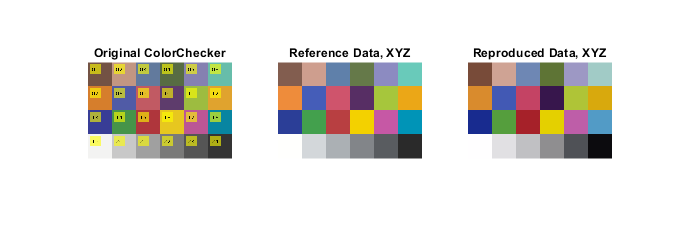

if strcmp(cpr.devDataOriginal.source,'XYZ')
    cpr.evaluate_visual_XYZ;
end

*Figure 3.1.1: Visual verification of the CIEXYZ data. The charts show the simulated visual results when using D65 as the reference white. Use these charts to check excessive color shift caused by the light source and/or the device. *

#### 3.1.2 Visualize CIELAB data

The following charts show the simulated visual results when using the provided reference white. Use these charts to assess how the device would reproduce the ColorChecker.

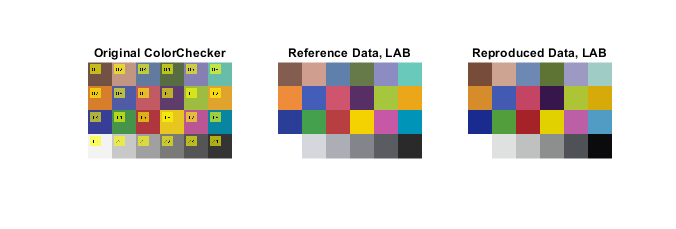

cpr.check_Lab_visual

*Figure 3.1.2: Visual verification of the CIELAB data. The charts show the simulated visual results when using the provided reference white. Use these charts to assess how the device would reproduce the test target.*

#### 3.1.3 Visualize endoscopic scene

The following charts show the simulated visual results of an endoscopic scence. Use the default polyp sample or provide a different image according to the intended use.

Superficial esophageal cancer (type 0–IIa) is identified as slight reddish lesion

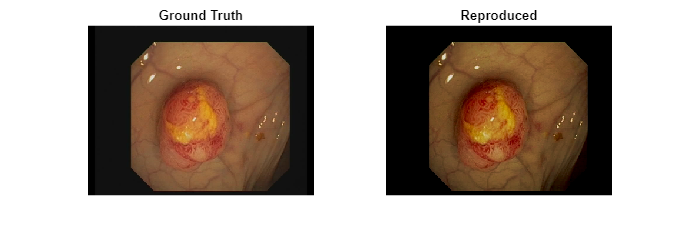

simulate_filename = "sample_polyp.png";
cpr.check_endoscopic_scene(simulate_filename);

*Figure 3.1.3: Visualize endoscopic scenes. The charts show the simulated visual results of an endoscopic scene. Use the default polyp sample or provide a different image according to the intended use.*

### 3.2 Absolute color errors in comparison with the ground truth

The left chart shows the per-patch color difference between the endoscopy device and the ground truth. The right chart shows the boxplot. Statistics (mean, std, min, median, and max) are provided in the titles.

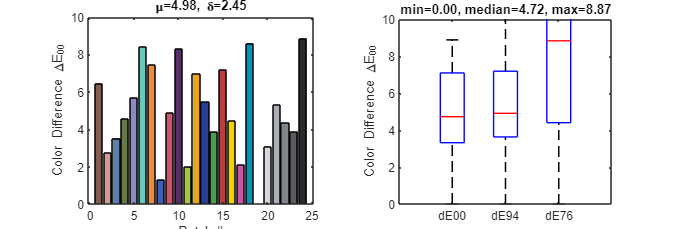

cpr.check_dE_from_truth

*Figure 3.2: Absolute color errors in comparison with the ground truth. The left chart shows the per-patch color difference between the subject device and the ground truth. The right chart shows the box plot. The statistics (mean, standard deviation, minimum, median, and maximum) are provided in the titles.*

### 3.3 Preservation of the patch order in lightness, hue, and chroma

#### 3.3.1 Order in lightness, chroma, and hue - 1D view

The following charts show the patch order in lightness, chroma, and hue (1D view). The top row is the reference, the bottom row is the device output, and each line connects the same patch. Use these charts to identify any out-of-order patches and assess concordance and monotonicity.

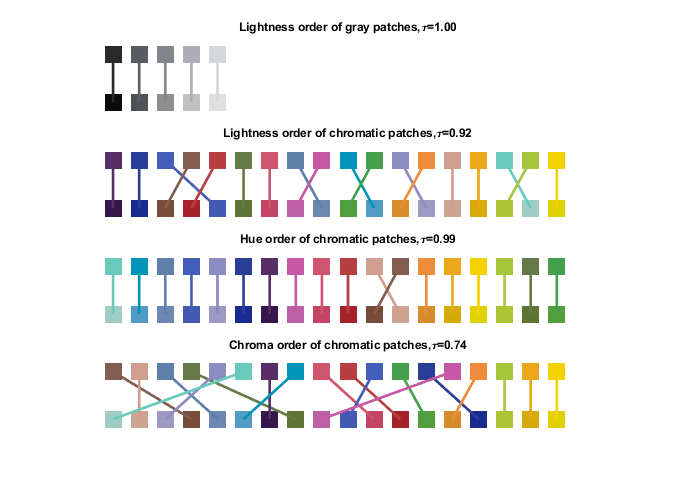

cpr.check_order

*Figure 3.3.1: Preservation of the patch order in lightness/hue/chroma -- monotonicity. The charts show the patch order in lightness, chroma, and hue. In each chart, the top row is the reference, the bottom row is the device output, and each line connects the same patch. The top chart shows the patch order in lightness for gray patches (#19-#24). The remaining three charts show the chromatic patches in the lightness, hue, and chroma order. Use these charts to identify any out-of-order patches. The Kendall Tau-a rank correlation coefficients are included in each plot.*

#### 3.3.2 Order in lightness, chroma, and hue - 2D view

The following charts show the patch order in lightness, chroma, and hue (2D view). Use these charts to identify any out-of-order patches and assess linearity, concordance, and monotonicity.

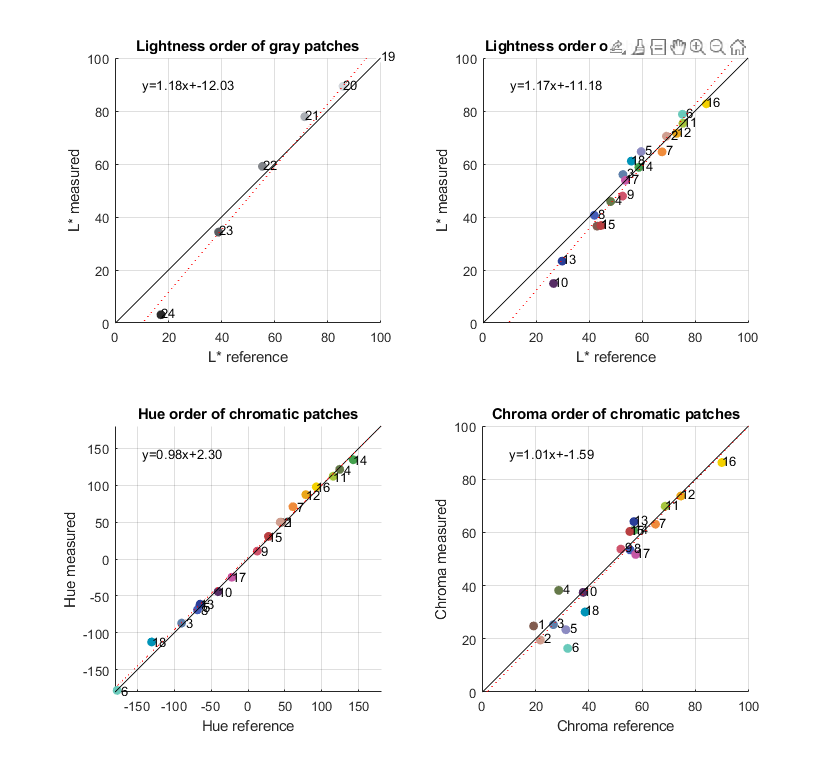

cpr.check_linearity

*Figure 3.3.2: Preservation of the patch order in lightness/hue/chroma -- linearity. The top two charts show the patch order in lightness for gray patches (#19-#24) and chromatic patches (#1-#18). The lower left chart shows the chromatic patches in the hue order, and the lower right in the chroma order. Linear regression coefficients are included in each plot.*

#### 3.3.3 Three-dimensional color transfer

The following charts show the color transfer from the ground truth (spheres) to the device output (crosses) of all patches in the CIELAB color space. Rotate the 3D plots in Matlab to observe the spatial relationship. 

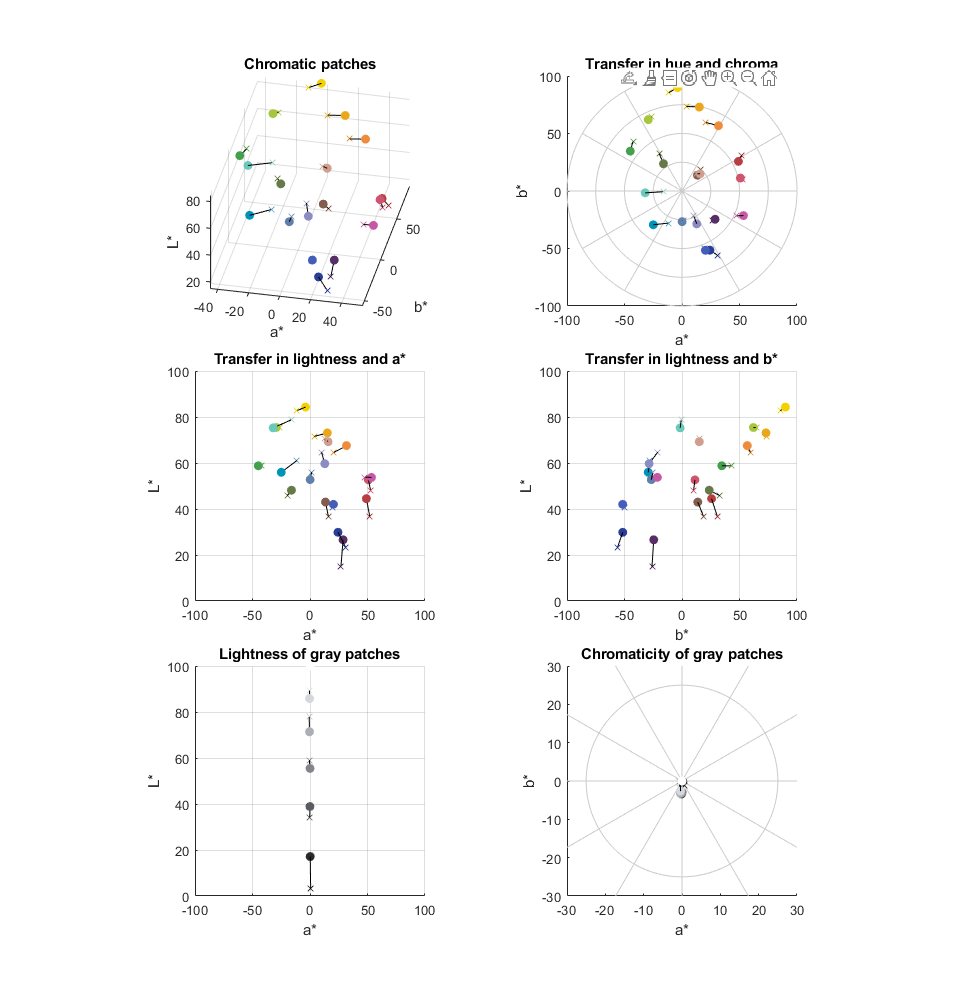

cpr.check_color_transfer

*Figure 3.3.3: Visualization of color transfer. The top four charts show the color transfer of the chromatic patches observed from different angles. The bottom two charts show the color transfer of the gray patches to observe their lightness and chromaticity.*

### 3.4 Preservation of Color Contrast between Patches

The following charts show all datapoints plotted according to their ground truth and device output. The color contrast enhancement (CCE) is defined as follows:

$CCE=\frac{\Delta{ E(sub(i),sub(j))}}{\Delta{ E(ref(i),ref(j))}$,

where $i$ and $j$ are patch numbers $1 \le i \le 24, 1\le j \le24, i \ne j$. $ref(i)
$ and $sub(i)$ are reference and subject device output for patch #$i$, respectively. $\Delta E$ is a function calculating the CIE color difference between two colors based on either the $\Delta E_{00}$, $\Delta E_{94}$, or $\Delta E_{76}$ formulas.

$CCE=1$ (represented by the dotted red line) means that the device reproduces the color contrast perfectly. $CCE>1$ means that the device enhances the color contrast, while $CCE<1$ means otherwise.

cpr.check_cce

*Figure 3.4: Preservation of color contrast between patches. The CCE values calculated based on the *$$\Delta E_{00}$$*, *$$\Delta E_{94}$$*, or *$$\Delta E_{76}$$* formulas. Each colored cross represents a patch-pair where the horizontal and vertical bars are colored separately according to the patch-pair. The percentage indicates patch-pairs that have *$$CCE \ge 1$$*.*

% close all figures
close all